clear
load fisheriris
X = meas;
Y = string(species);

cv = cvpartition(Y,'Holdout',0.65);
X_training = X(cv.training,:); Y_training = Y(cv.training);

fileDirectory = fullfile('D:/Proton Drive/Lasseb200/My files/Master/MachineLearning');
addpath(fullfile(fileDirectory,'LinearSVM'));
X_test = X(cv.test,:);
Y_pred = LinearSVM_1v1(X_training,Y_training,X_test,1)

Y_pred = 97×1 string array
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"
    "setosa"


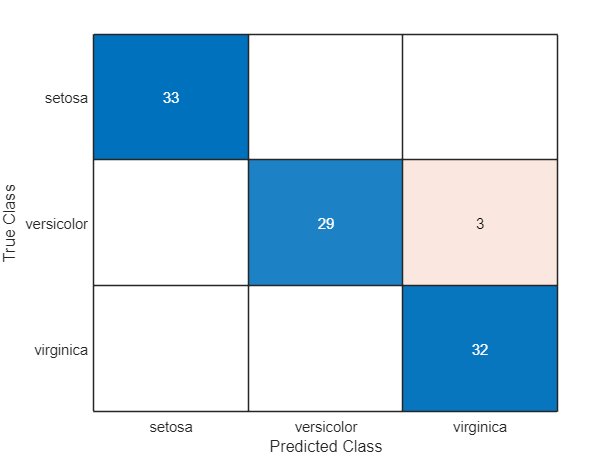



Y_test = Y(cv.test);
confusionchart(Y_test, Y_pred);


tic
Mdl = fitcecoc(X_training, Y_training,'Learners','linear');
Y_pred_bi = string(predict(Mdl, X_test));
toc

Elapsed time is 0.049776 seconds.


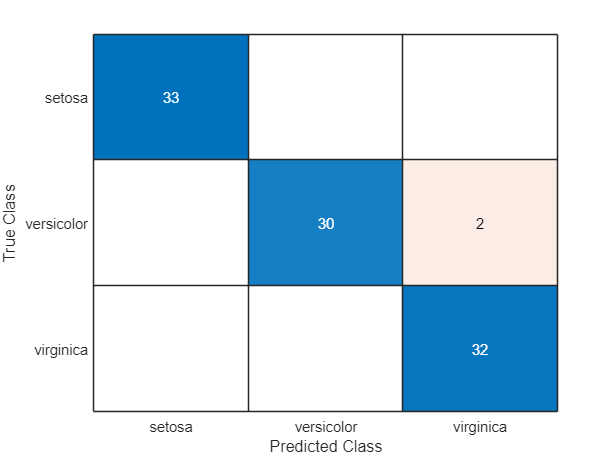


confusionchart(Y_test, Y_pred_bi);